## Interpolare Lagrange

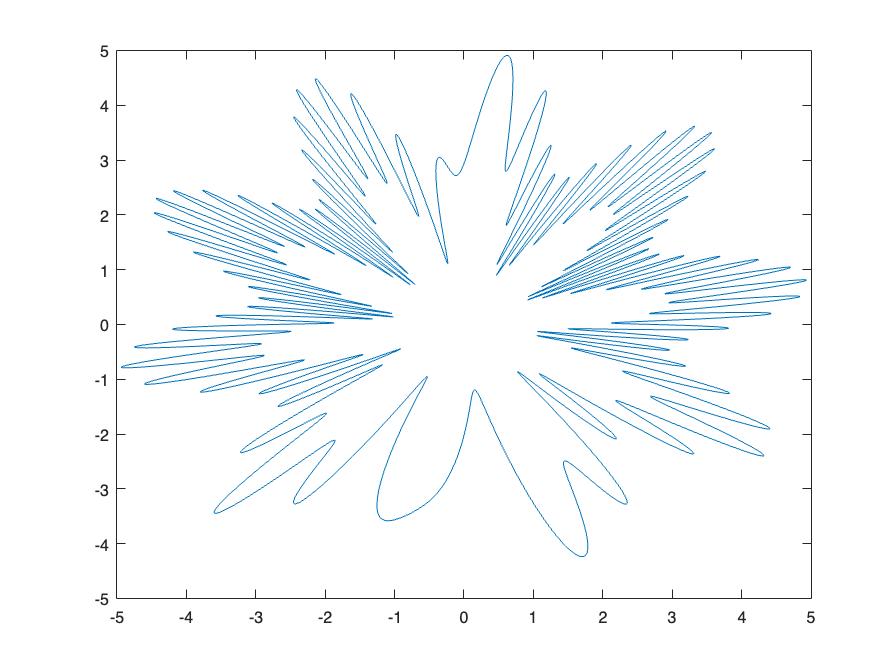

f = @(x) (3 + sin(10 * pi * x) + sin(61 * exp(0.8 * sin(pi * x) + 0.7))) .* exp(1i * pi * x);

close all
m = 671;
k = 0:m;
xn = cos(k * pi / m);
yn  = f(xn);
t = linspace(-1, 1, 10000);
z = ChebLagrange(yn, t);
plot(z)